## Introducing Transparency to Legends and Rectangles

**Guest Writer: **[**Afiq Azaibi**](https://www.mathworks.com/matlabcentral/profile/authors/8450560) 

Today's R2024a feature highlight is written by [Afiq Azaibi](https://www.mathworks.com/matlabcentral/profile/authors/8450560), a developer on the Charting Team and a returning contributor to the Graphics and App Building blog.  See Afiq's full bio in our [contributors page](https://blogs.mathworks.com/graphics-and-apps/contributors/). 

Sometimes a legend or rectangle can occlude data behind it. You can make both objects fully transparent by setting the legend's `Box` property to `'off'` or setting the rectangle's `FaceColor` property to `'none'` respectively but this could be undesirable in some situations. Starting in R2024a, we introduced features to control the transparency of both legends and rectangles. Let's take a look at an example using weather data around the MathWorks HQ located in Natick, MA from [ncei.noaa.gov](http://ncei.noaa.gov) ([download link](https://github.com/MATLAB-Graphics-and-App-Building/matlab-gaab-blog-2024/raw/main/LegendAndRectangleAlpha/natickWeatherTbl.mat)).

load natickWeatherTbl.mat
head(natickWeatherTbl)

       Date       Precipitation    Max Daily Temperature    Min Daily Temperature
    __________    _____________    _____________________    _____________________

    01/01/2010        0.12                  29                       22          
    01/02/2010         0.1                  33                       25          
    01/03/2010        0.25                  29                       13          
    01/04/2010        0.06                  27                       14          
    01/05/2010           0                  34                       20          
    01/06/2010           0                  32                       19          
    01/07/2010           0                  32                       19          
    01/08/2010           0                  39                       18          



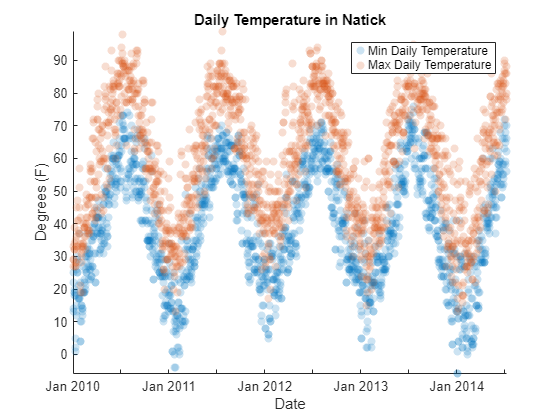

s = scatter(natickWeatherTbl,"Date", ["Min Daily Temperature" "Max Daily Temperature" ],'filled', 'MarkerFaceAlpha',.2);
axis tight;
leg = legend;
title("Daily Temperature in Natick");
ylabel("Degrees (F)");

The legend is obscuring part of the scatter charts. Starting in R2024a, we can update the `BackgroundAlpha` property which makes the legend semi-transparent. Now we can see data points behind the legend. If you find yourself in a situation where you can't set the legend's location to be outside and all the locations inside would obscure data, consider leveraging the legend's `BackgroundAlpha` property.

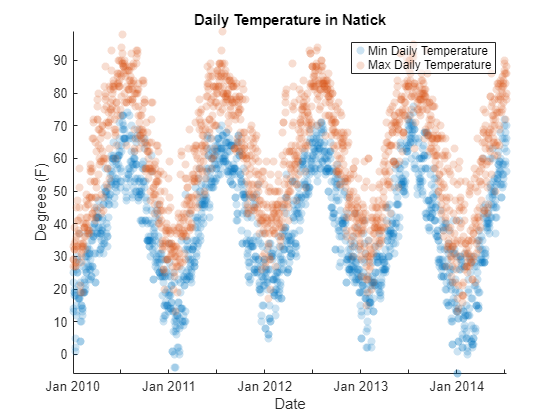

leg.BackgroundAlpha = .6;

Additionally, if we wanted to highlight the most number of days below 0 during the winter of 2011, we could add a [rectangle](https://www.mathworks.com/help/matlab/ref/rectangle.html) in this region. The filled rectangle unfortunately obscures the data.

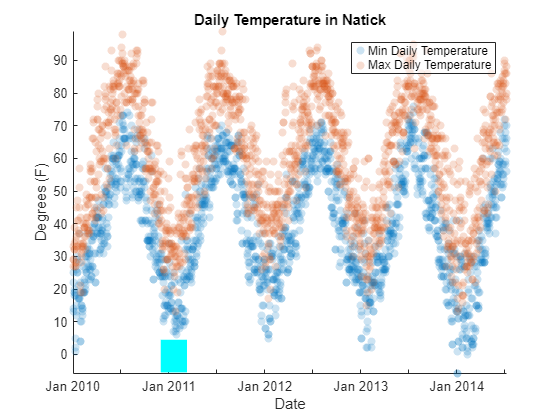

x = days(natickWeatherTbl.Date(335)-natickWeatherTbl.Date(1));
rect = rectangle('Position',[x,-5.5,100,10], 'EdgeColor', 'none', 'FaceColor', 'c');

Starting in R2024a, rectangle has a `FaceAlpha` property which can be used to change the rectangle's transparency.

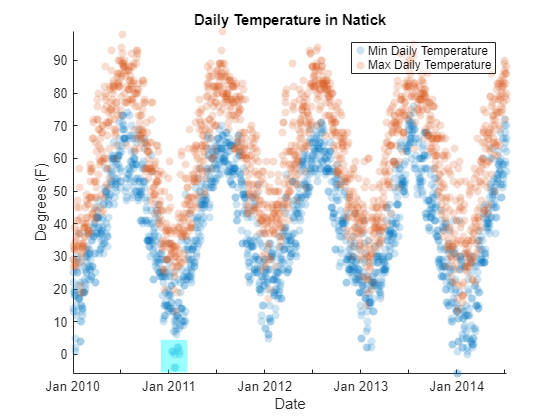

rect.FaceAlpha = .4;

Previously the only workaround for this would be to update the child order of the axes such that the scatter markers render on top of the rectangle. Now that rectangle has `FaceAlpha`, you can choose between the two options depending on whether you want the rectangle to overlay the data or not.